% Just loading up the values that SEEM like theyre correct.
% ts is actually unreadable
cd /home/harry/Documents/uni/2025F/EEE5119Z/EEE5119Z_Project/
load('sim_data_single.mat');
c = 3e8; % m/s
delta = p.B / p.ts; % rate of frequency change

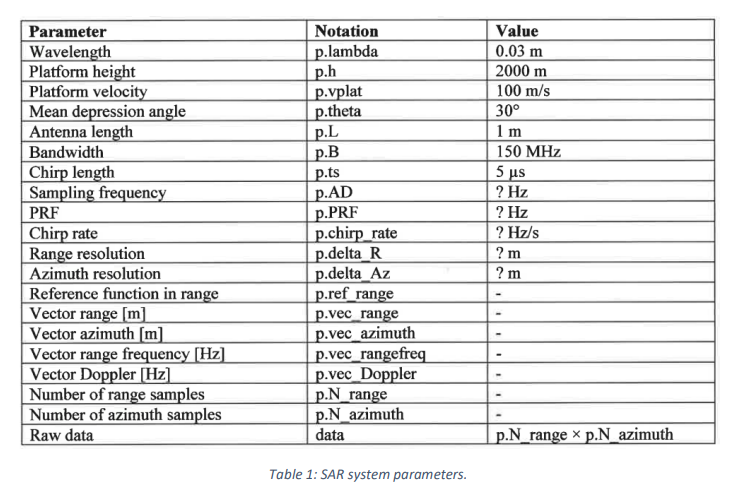

# Question 1 - SAR Signal Simulator

## 1)

**Determine the sampling frequency to avoid range ambiguities and the PRF to avoid azimuth ambiguities due to sub-sampling. Give theoretical resolutions in range and azimuth (hint: use IQ sampling)**

base_frequency = c/p.lambda; % Around 10 GHz

% Max range is the outer part of the beam, so need to use some trig
beam_center_length = p.h / sin(p.theta); % The range of the middle of the beam

% If aperture is in the direction of motion, then p.L informs beamwidth and
% which informs the max range
beamwidth = 0.89 * p.lambda / p.L;
max_range = p.h / sin(p.theta - beamwidth/2); % Simple trig if the depression angle gets smaller

Max unambiguous range is $R_{max} = \frac{c}{2 \cdot PRF} = \frac{c \cdot PRI}{2}$, and recall that $\Delta R = \frac{c}{2B}$

% So
PRF_min = c / (2 * max_range); % Increasing Rmax means decreasing PRF
p.delta_R = c/(2*p.B); % I mean this makes sense
% azimuth resolution is apparently 1/length of antenna?

% PRF gives us max range (unambiguous)
% PRF gives max measurable doppler
% Can sample at B because of downsampling and IQ

f_sample = p.B;

% - [x]sampling freq for no range ambiguities
% - [ ]prf for no azimuth ambiguities
% - [ ]theoretical range and azimuth resolutions

## 2)

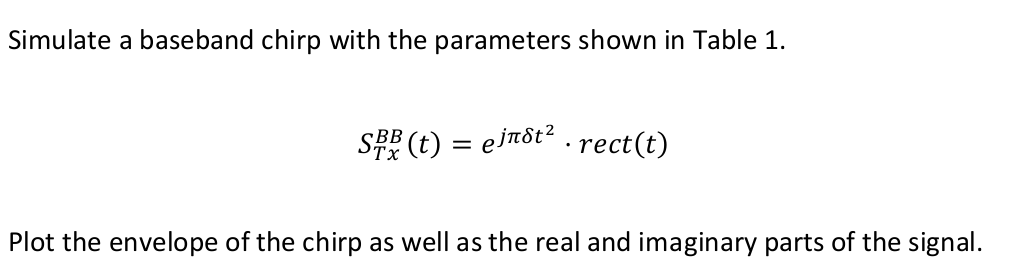

% Generating Sbb
dt = 0.01; % Time divisions for our time domain
t = -5: dt :5-dt; % Time vector
rect_width = 4; % width of the rectangular window
S_bb = exp(1j*pi*delta*t.^2) .* transpose(rect_function(t, 0, rect_width)); % Define signal 1

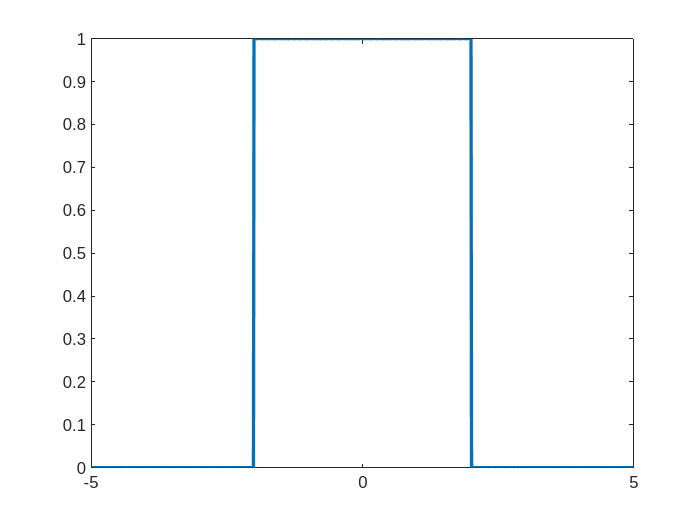

% Plotting the envelope of the chirp, I think its just the rect function so
% whatever
figure
plot(t, transpose(rect_function(t, 0, rect_width)), LineWidth=2);

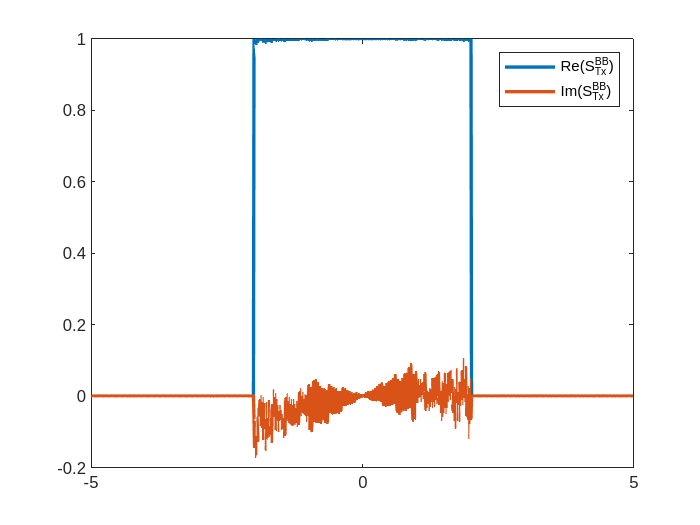

figure
plot(t, real(S_bb), LineWidth=2);
hold on
plot(t, imag(S_bb), linewidth = 2);
legend({'Re(S_{Tx}^{BB})','Im(S_{Tx}^{BB})'},'Location','northeast')

## 3)